**1. Load in the image**

% folders completed: 76O WT

filePath = '/MATLAB Drive/colony assay/786-O WT cell line';
cd (filePath);
fileList = dir(fullfile(filePath, '*.jpg'));  % List all PNG files (modify the extension as needed)

% Extract the filenames from the structure
filenames = {fileList.name}

filenames = 1x23 cell array
    {'1.jpg'}    {'10.jpg'}    {'11.jpg'}    {'12.jpg'}    {'13.jpg'}    {'14.jpg'}    {'15.jpg'}    {'16.jpg'}    {'17.jpg'}    {'18.jpg'}    {'2.jpg'}    {'3.jpg'}    {'4.jpg'}    {'5.jpg'}    {'6.jpg'}    {'7.jpg'}    {'8.jpg'}    {'9.jpg'}    {'MONTAGE 1.jpg'}    {'MONTAGE 10.jpg'}    {'MONTAGE 11.jpg'}    {'MONTAGE 12.jpg'}    {'MONTAGE 13.jpg'}


photoNumber = length(filenames);
%allow user to use slider to iterate through images in the specified folder
%(don't have to type in image neame each time)
i =1;
imgTitle = string(filenames(i))

imgTitle = "1.jpg"

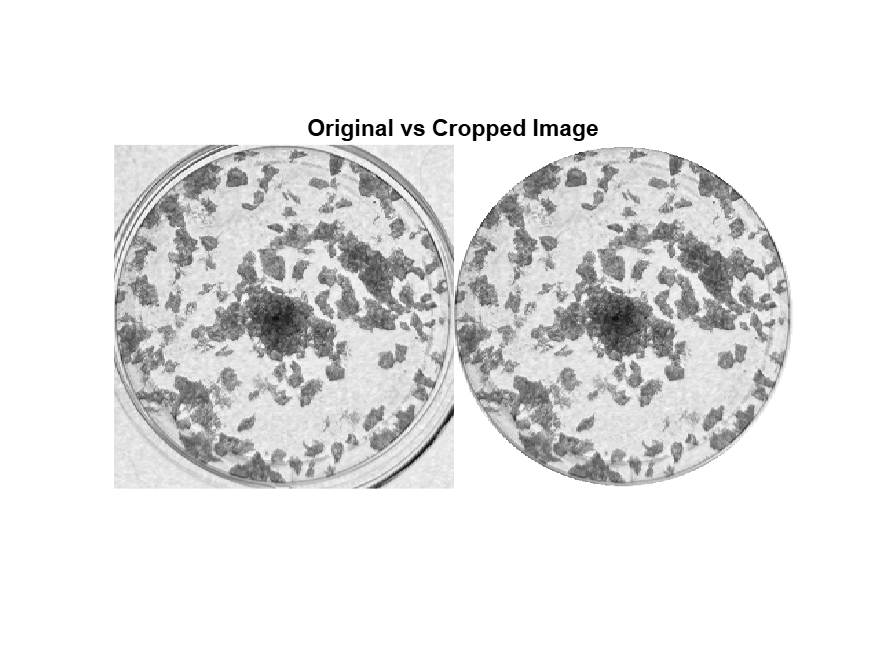

img1 = imread(imgTitle); %read in image
img = rgb2gray(img1); %convert to grayscale
img_blurred = imgaussfilt(img);

%cut out the center region representing the cells in the dish

% Get the size of the image
[rows, cols] = size(img_blurred);

% Calculate the radius of the circular region
radius = min(rows, cols) / 2;

% Calculate the center coordinates of the circular region
centerX = round(cols / 2);
centerY = round(rows / 2);

% Create a meshgrid of coordinates
[X, Y] = meshgrid(1:cols, 1:rows);

% Calculate the distance of each point from the center
distances = sqrt((X - centerX).^2 + (Y - centerY).^2);

% Create a logical mask where the values inside the circle are set to true (1)
mask = distances <= radius;

% Create a white background image
background = ones(size(img_blurred), 'like', img_blurred) * 255;

% Apply the mask to the background
img_cropped = img_blurred .* uint8(mask) + background .* uint8(~mask);

% Display Photos
montage({img_blurred, img_cropped})
title('Original vs Cropped Image')

**2. Binarize the Image**

(don't worry about small holes in this step)

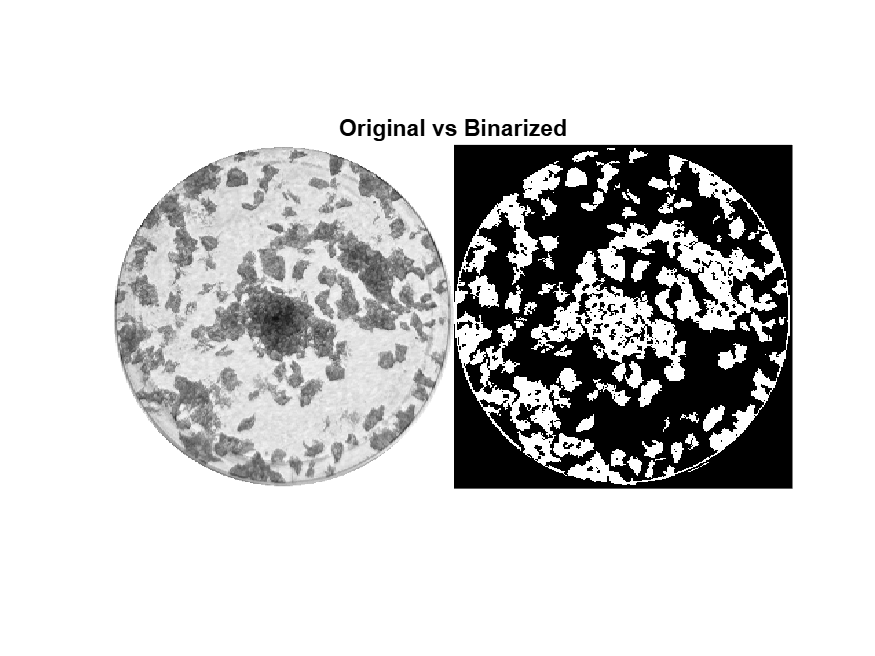

%threshold using variance:      
% Define the window sizes for variance calculation
        windowSizes = [3, 5, 7, 9];
        
        % Initialize a mask to store the blurry regions
        blurryMask = false(size(img_cropped));
        
        % Calculate variance at different window sizes
        for i = 1:numel(windowSizes)
            windowSize = windowSizes(i);
            
            % Calculate the local variance using imfilter and imgaussfilt
                localVariance = imfilter(double(img_cropped).^2, ones(windowSize)/windowSize^2, 'replicate') - imgaussfilt(double(img_blurred), windowSize).^2;
            
            % Find the blurry regions based on variance values
            blurryRegions = localVariance <= 80;
            
            % Accumulate the blurry regions
            blurryMask = blurryMask | blurryRegions;
        end
        
        % Apply the blurry mask to the original image
        blurryImage = img_cropped;
%         aboveThresholdMask = img_blurred > graythresh(img_blurred);
%          blurryImage(blurryMask & aboveThresholdMask) = 0;  % Set to white

        blurryImage(~blurryMask) = 0; %create an image that displays original
        % grayscale values of blurry regions, and non-blurry regions set to 0 (black)
        
        
    blurryBinary = ~blurryImage; %Binary image where white = blurry regions
    
   brightnessThreshold =185; % Example threshold value that the cells have to be darker than to count as foreground
    
    % Create a binary mask for regions above the brightness threshold
    aboveThresholdMask = img_blurred > brightnessThreshold;
    
    % Set the corresponding regions in 'back' to white
    blurryBinary(aboveThresholdMask) = 1;    

    % Apply a threshold to separate foreground and background
    [thresholded, sensitivity] = adaptiveThreshold(img_blurred); 

    thresholded(blurryBinary) = 1;
    bw = thresholded;

     figure

    colormap gray
%create complement & get rid of small specs
bw2 = ~bw;
denoised = bwareaopen(bw2, 30);

montage({img_cropped, denoised})
title('Original vs Binarized')

**3. Fill in small holes if necessary**

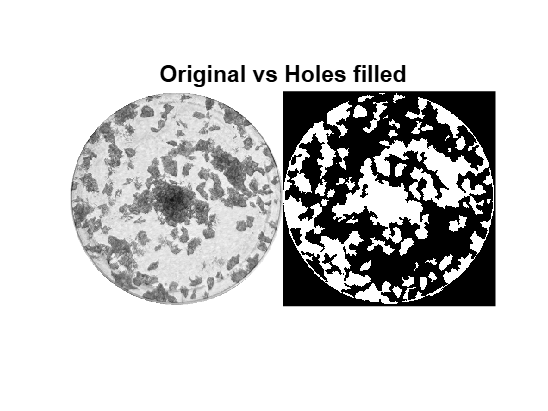

% %dilation/erosion to solidify cell parts & get rid of noise
se = strel('disk', 2);
dilated = imdilate(denoised, se);
figure
eroded = imerode(dilated, se);
% cleaned1 = bwareaopen(eroded, 1000); %get rid of white noise
cleaned2 = ~bwareaopen(~eroded, 250); %fill in small black holes
 

montage({img_cropped, cleaned2});
title('Original vs Holes filled');


cleaned2 = denoised;

**4. Calculate& Save Colony Area %**

tableName = "clonogenic___"+'.xls'; %excel file where you want to store analysis stats

 
%store final img & data
C = imfuse(cleaned2,img_blurred,'montage');
%imshow(C)

S = extractBefore(imgTitle, '.jpg');
fileName = "MONTAGE " + S + '.jpg';
imwrite(C,fileName)

if ~isfile(tableName) %if the table does not already exist
    colNames = {'Photo Name', 'Percent Colony Area'};
    data = cell(1,2); % create a cell array with one row and the same number of columns as colNames
    table = [cell2table(colNames, 'VariableNames', colNames); cell2table(data, 'VariableNames', colNames)]
    writetable(table, tableName);
    existingTable = readtable(tableName);
    existingTable(1,:) = []; %remove duplicate column names row
else
    existingTable = readtable(tableName); %no need to remove duplicate col name row in this case
end

fprintf('This table is stored as %s in %s:', tableName, filePath)

This table is stored as clonogenic___.xls in /MATLAB Drive/colony assay/786-O WT cell line:


newRow = {imgTitle, bwarea(cleaned2)/numel(cleaned2)}; 


data = [existingTable;newRow]; %add data from analysis
% Find the unique values in PhotoName column
[~, ia, ~] = unique(flipud(data.PhotoName),'rows', 'stable');
ia = size(data,1) - ia + 1;% Select only the rows that contain unique values. If you ran code for
% the same image >1 time, the program will save the most recent version of
analysisStats = flipud(data(ia, :))

analysisStats = 1x2 table
    PhotoName    PercentColonyArea
    _________    _________________

     "1.jpg"          0.30109     



writetable(analysisStats, tableName, 'WriteMode', 'overwrite'); %add data to table